# **IO611 - LIN Loopback **

This example shows how to run a simple loopback using the IO611 I/O module. The IO611 features 2 isolated channels for CAN FD and High-Speed CAN and 2 isolated channels for LIN.

The Simulink model implements a unidirectional LIN loopback transmitting data from channel 2 to channel 1.

This example demonstrates the following modes and features:

- Communication between a pair of LIN channels on an IO611 I/O module 

- Using the Vector Concatenate and several Selector blocks with a LIN Write and LIN Read block

- Using the Byte Packing and Byte Unpacking blocks with a LIN Write and LIN Read block

- Using the LIN Pack and LIN Unpack blocks with a LIN Write and LIN Read block

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO611 I/O module installed

- 1x LIN loopback cable according to the [IO611 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io611_pin_mapping)

- 1x external power supply capable of outputting 8-18 V

### Connection Diagram

For this example, connect LIN channel 1 and channel 2 in a loopback configuration. Refer to the diagram below for the necessary pin wiring. Additionally an external power supply is required to power the LIN Bus with a voltage between 8 V and 18 V.

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO611_LIN_Loopback';
open_system(modelName);

## Model Description

The Simulink model contains one subsystems that represent the LIN communication. This subsystem is used to send LIN messages from channel 1 to channel 2.

The LIN communication is controlled by the LIN Read blocks configured as Master. The Master on channel 1 sends out a header requesting a response from a Slave on channel 2 with a matching ID. All [LIN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2_lin_read) blocks are placed inside a triggered subsystem which executes the blocks alternately. This to schedule the communication on the LIN Bus in order to avoid conflicting header requests.

### Sending LIN Data from Channel 1 to Channel 2

 
% open Ch1RxMaster_Ch2TxSlave subsystem
speedgoat.model.highlight([modelName '/Ch1RxMaster_Ch2TxSlave'],'Open',true);

In this subsystem, on the left-hand side, each of the eight signals are prepared differently to be sent as a LIN message. The first option utilizes the [Vector Concatenate](https://ch.mathworks.com/help/simulink/slref/vectorconcatenate.html) block to combine multiple uint8 signals into an 8-byte uint8 vector. The second option utilizes the [Byte Packing](https://ch.mathworks.com/help/slrealtime/io_ref/bytepacking.html) block to combine multiple uint8 signals into an 8-byte uint8 vector. The third option utilizes the [LIN Pack](https://ch.mathworks.com/help/slrealtime/io_ref/linpack.html) block to load and parse a .ldf file. This file describes a set of uint8 signals to be packed into a LIN frame and output as an 8-byte uint8 vector. All of these vectors are wired to a [LIN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2_lin_write) block with LIN message IDs 48, 49 and 50.

On the right-hand side, the expected LIN message IDs are specified separately in two [LIN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2_lin_read) block masks. Consequently, the two IDs are available as outputs on the respective block mask. The division of the 8-byte LIN messages into signals is again done differently for each message. The first option utilizes the [Selector](https://ch.mathworks.com/help/simulink/slref/selector.html) block to index which uint8 to grab from the vector. The second option utilizes the [Byte Unpacking](https://ch.mathworks.com/help/ecoder/ref/byteunpack.html) block to map the signals to an output. The third option utilizes the [LIN Unpack](https://ch.mathworks.com/help/slrealtime/io_ref/linunpack.html) block to parse the same .ldf file again to unpack the LIN frame to output single signals again.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Select and load the .ldf file for the LIN Pack and Unpack blocks
set_param([modelName, '/Ch1RxMaster_Ch2TxSlave/LIN Pack'], 'LDFFileName', 'LINDescriptorFile.ldf', 'selectedFrameName', 'Frame_06');
set_param([modelName, '/Ch1RxMaster_Ch2TxSlave/Enabled Subsystem2/LIN Unpack'], 'LDFFileName', 'LINDescriptorFile.ldf', 'selectedFrameName', 'Frame_06');

% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download the real-time application to the target machine and set stop time
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   
set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Wait until the real-time application reaches the stop time of 10 seconds

### Results

During the simulation, open the Simulink scopes or use SDI to view the data. The output should look as follows:

#### Ch1RxMaster_Ch2TxSlave

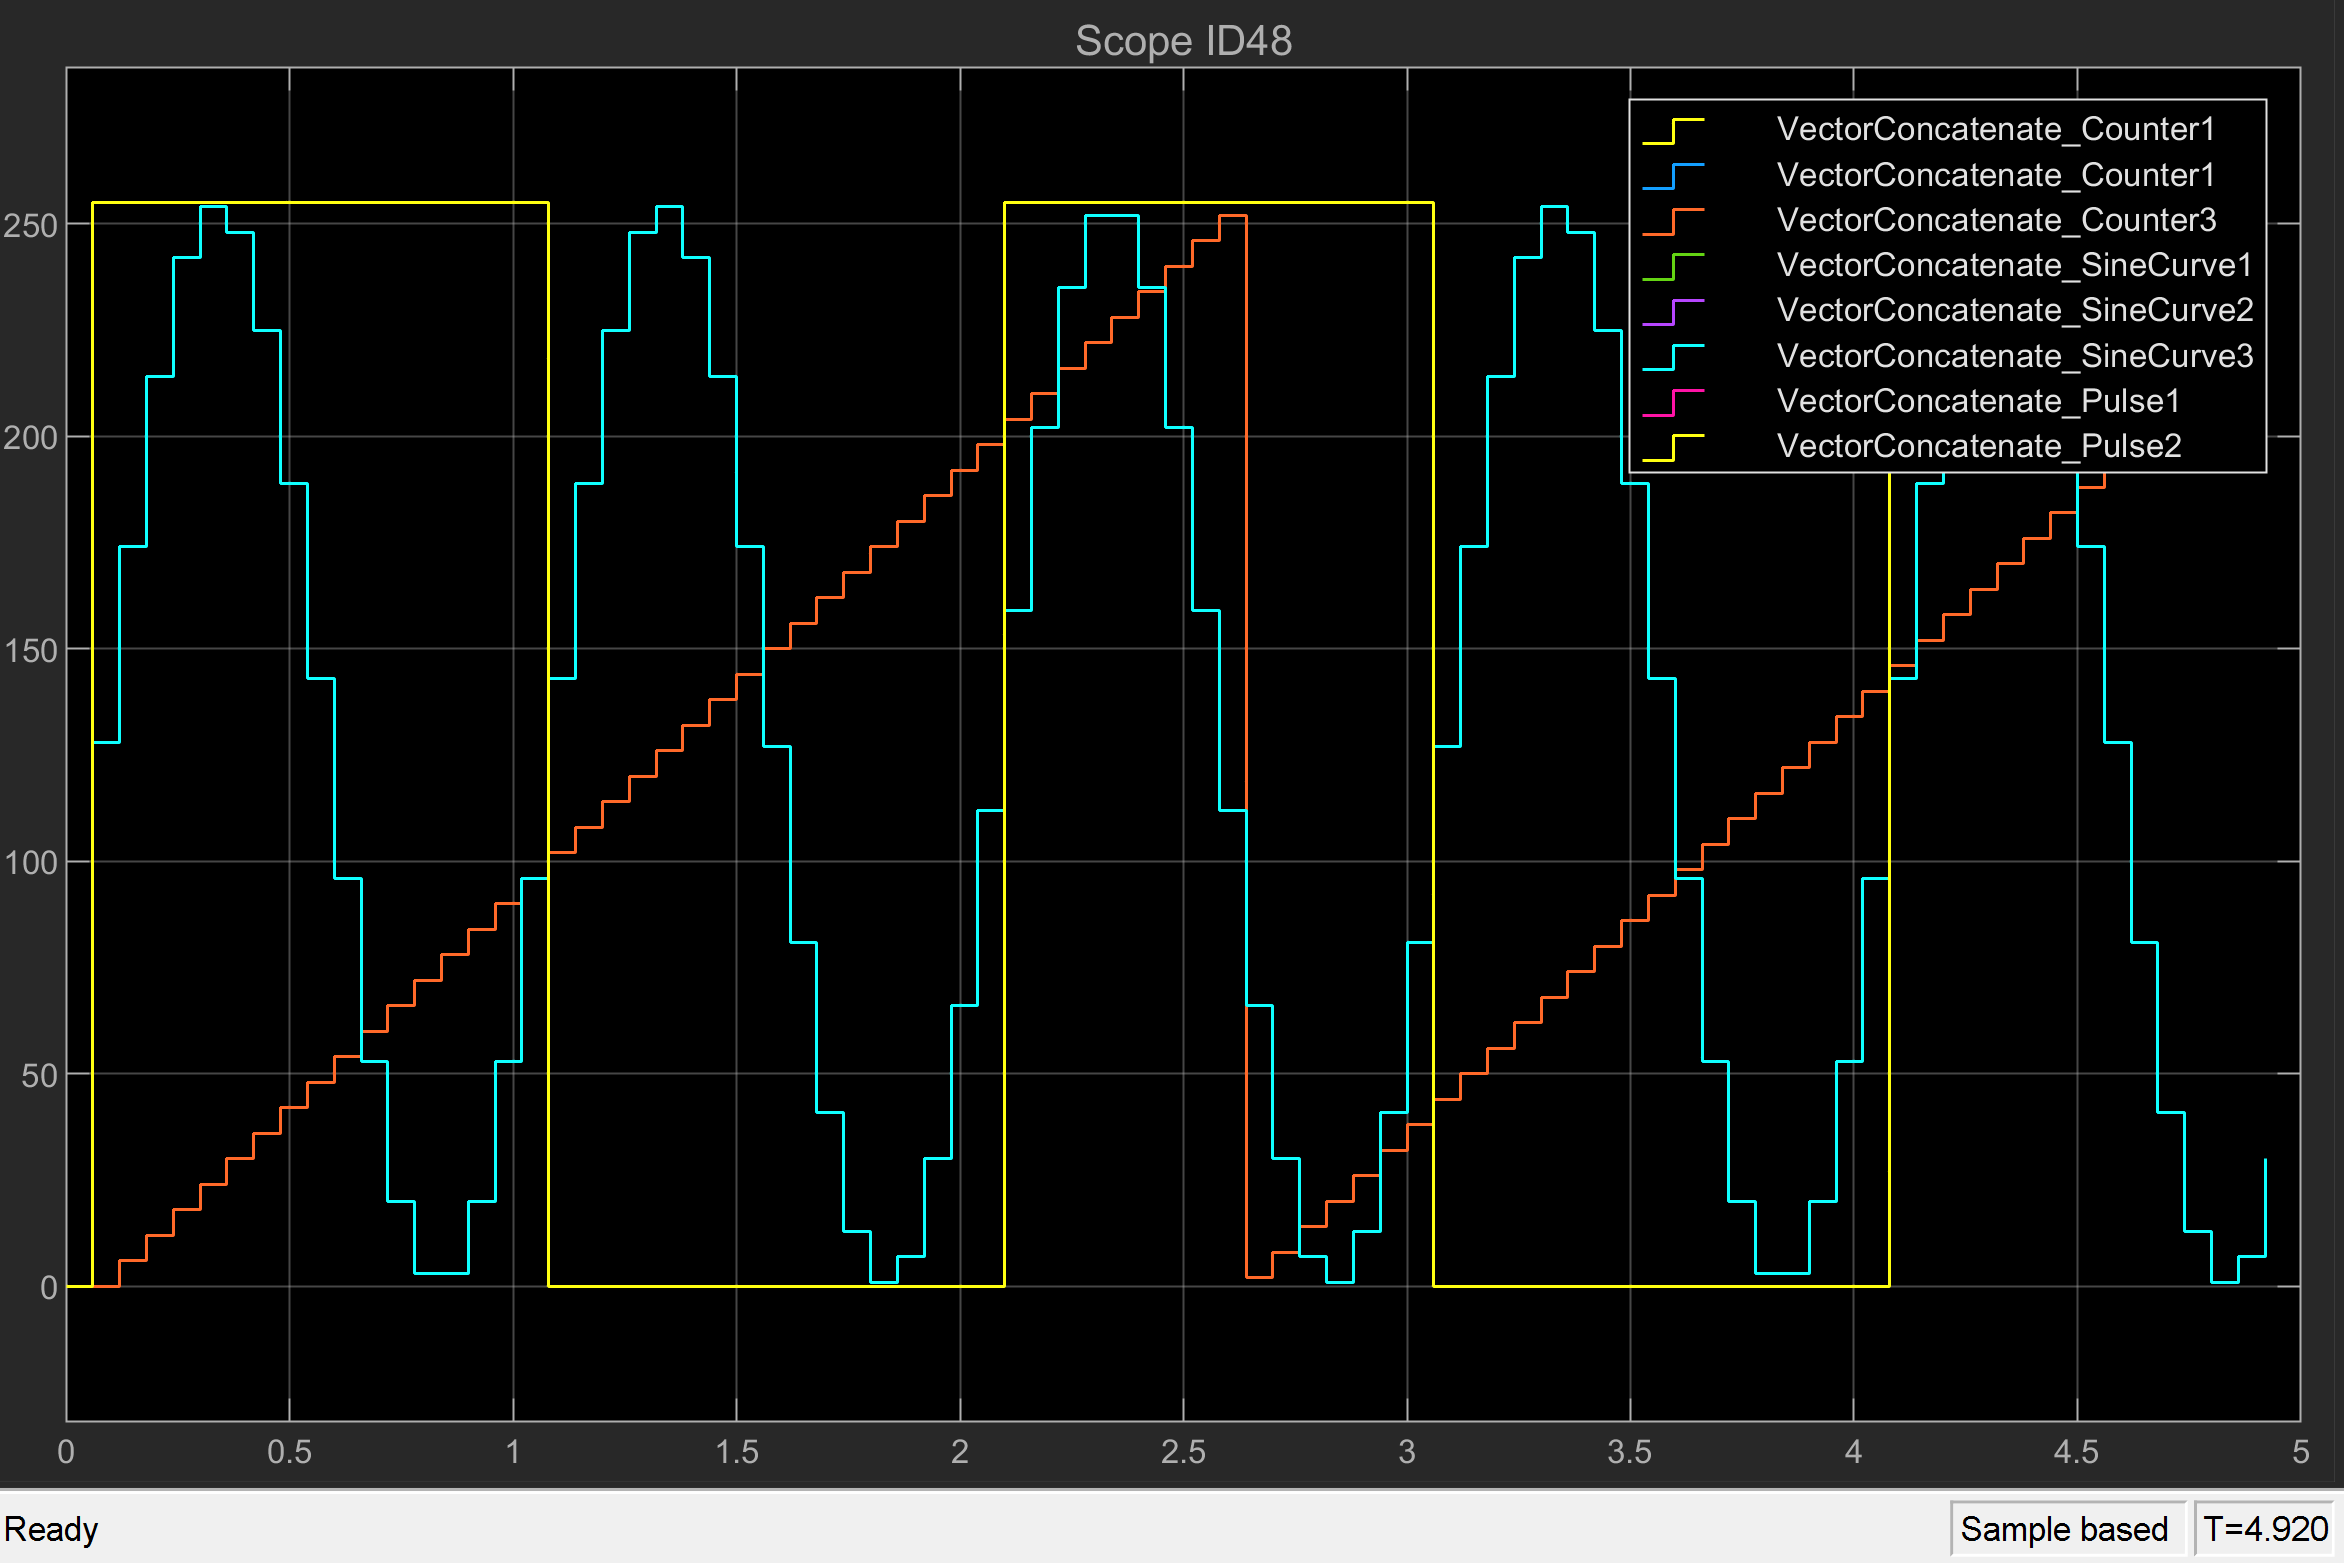

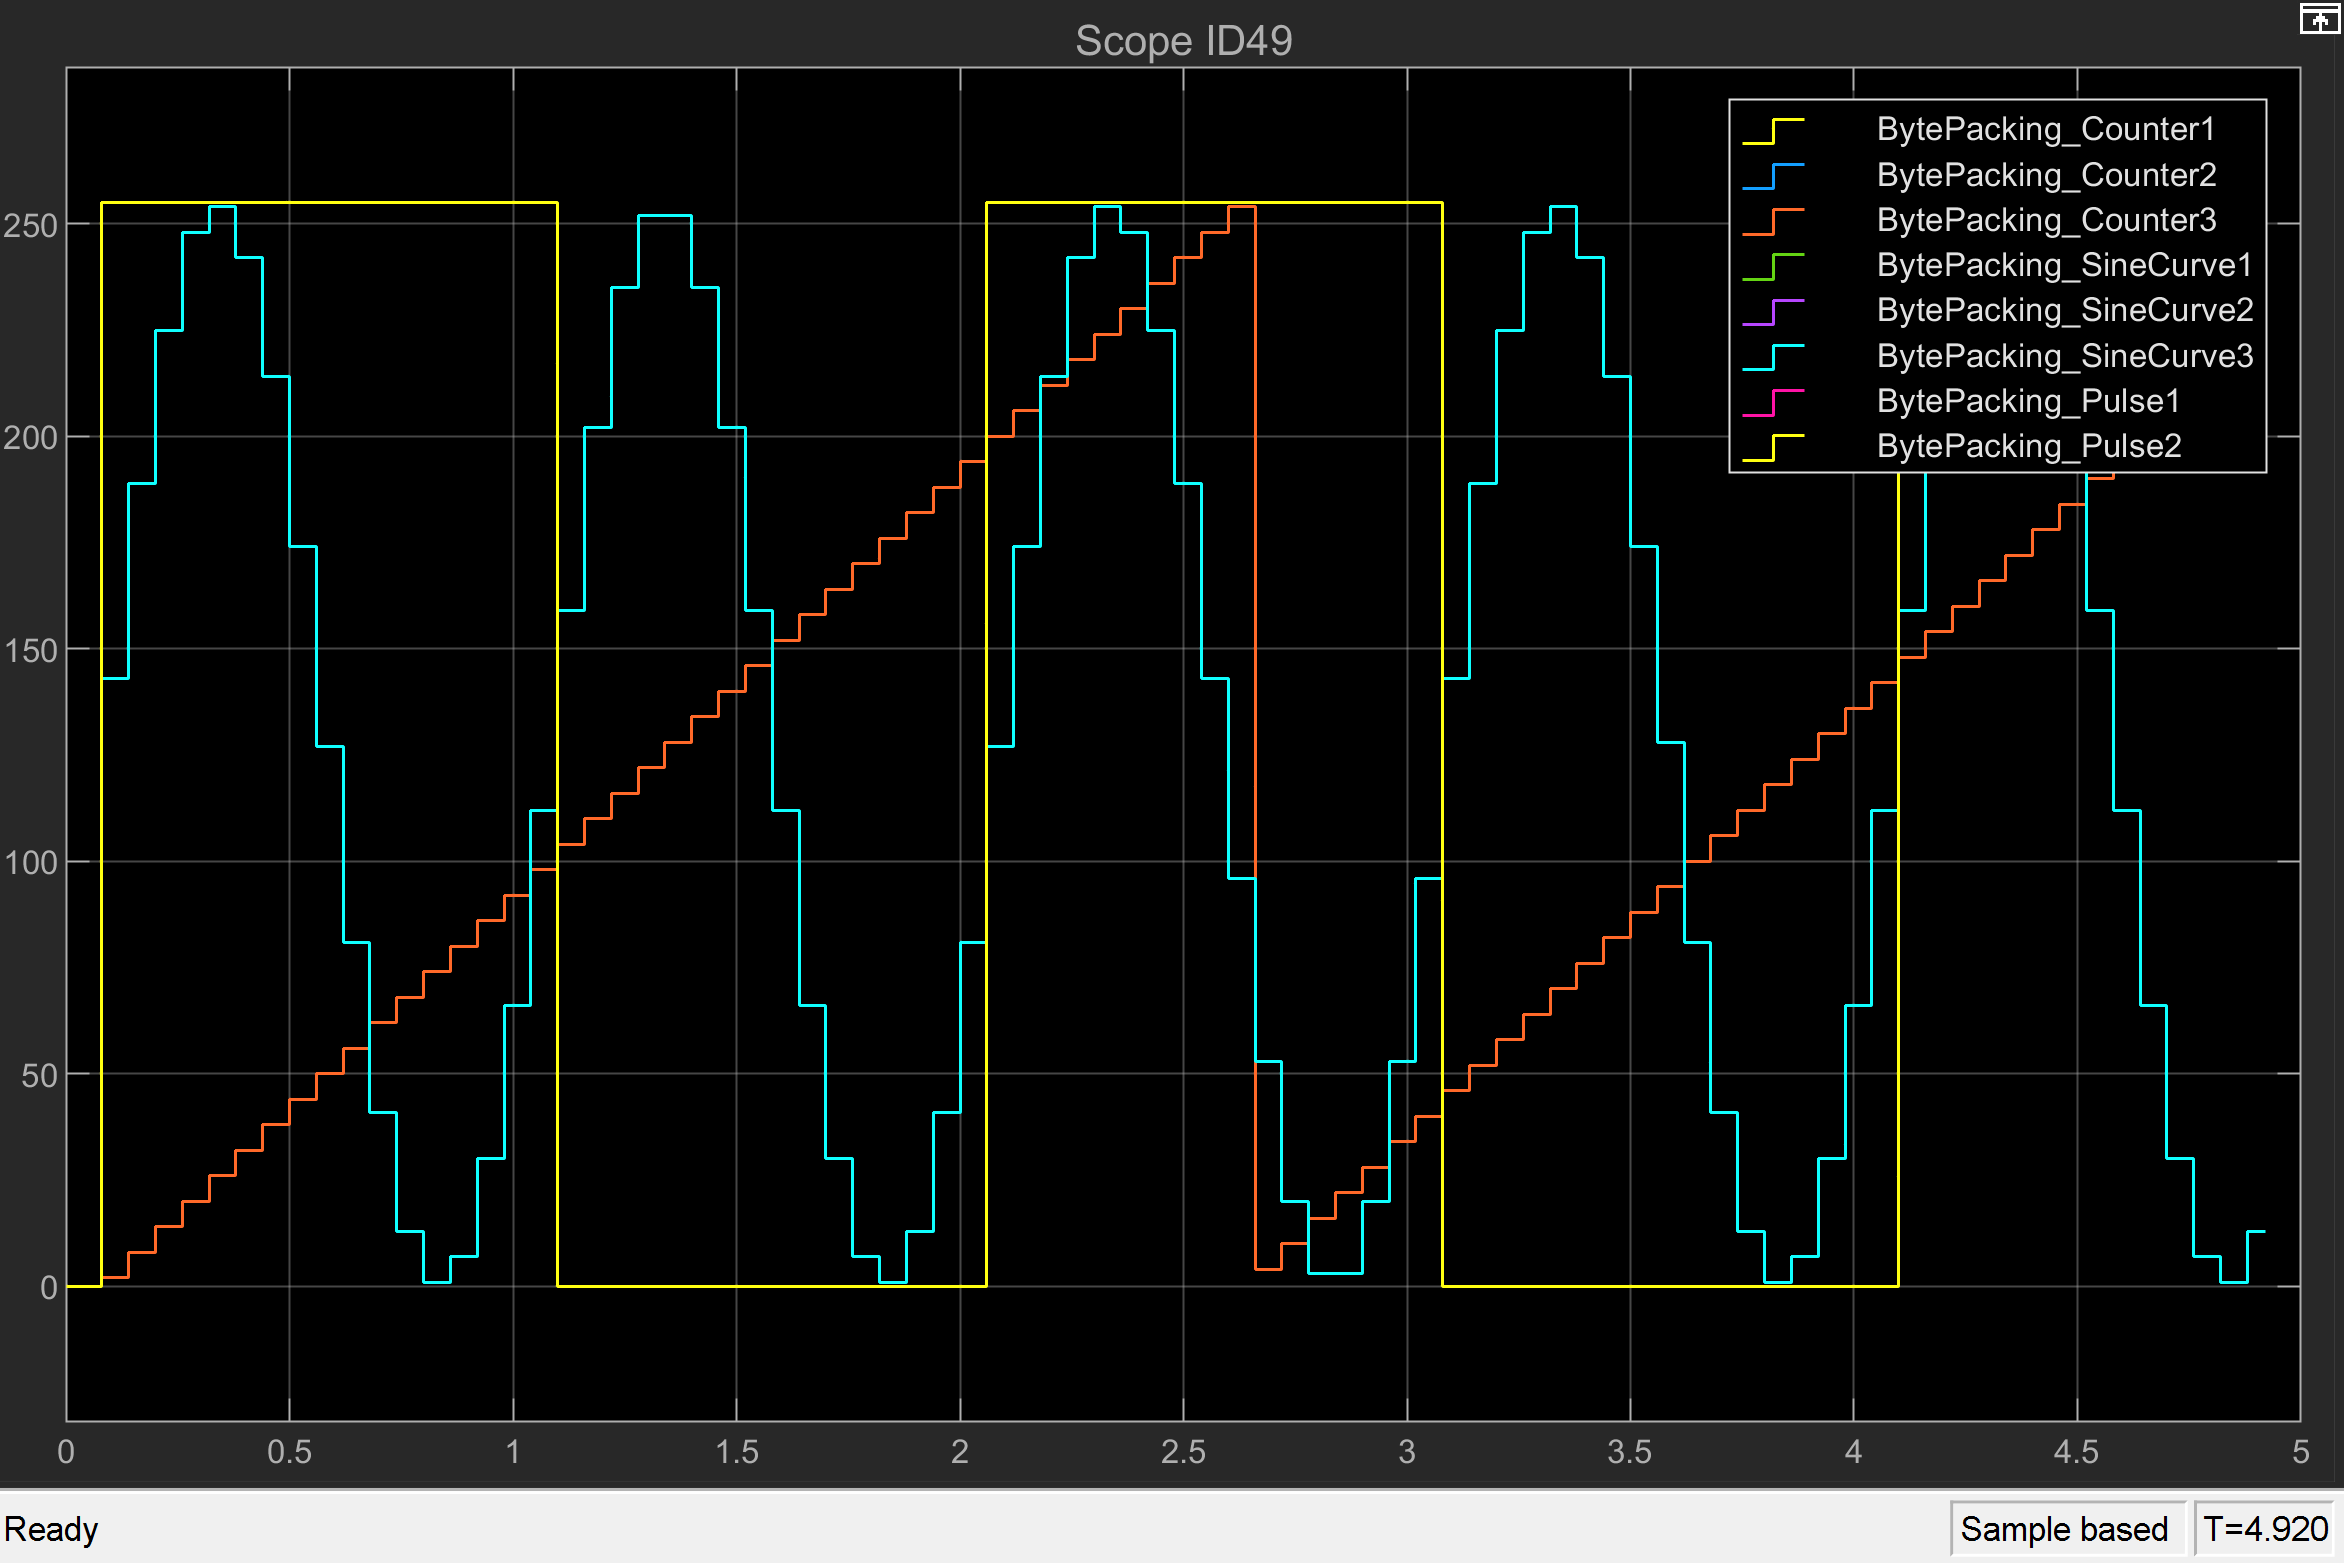

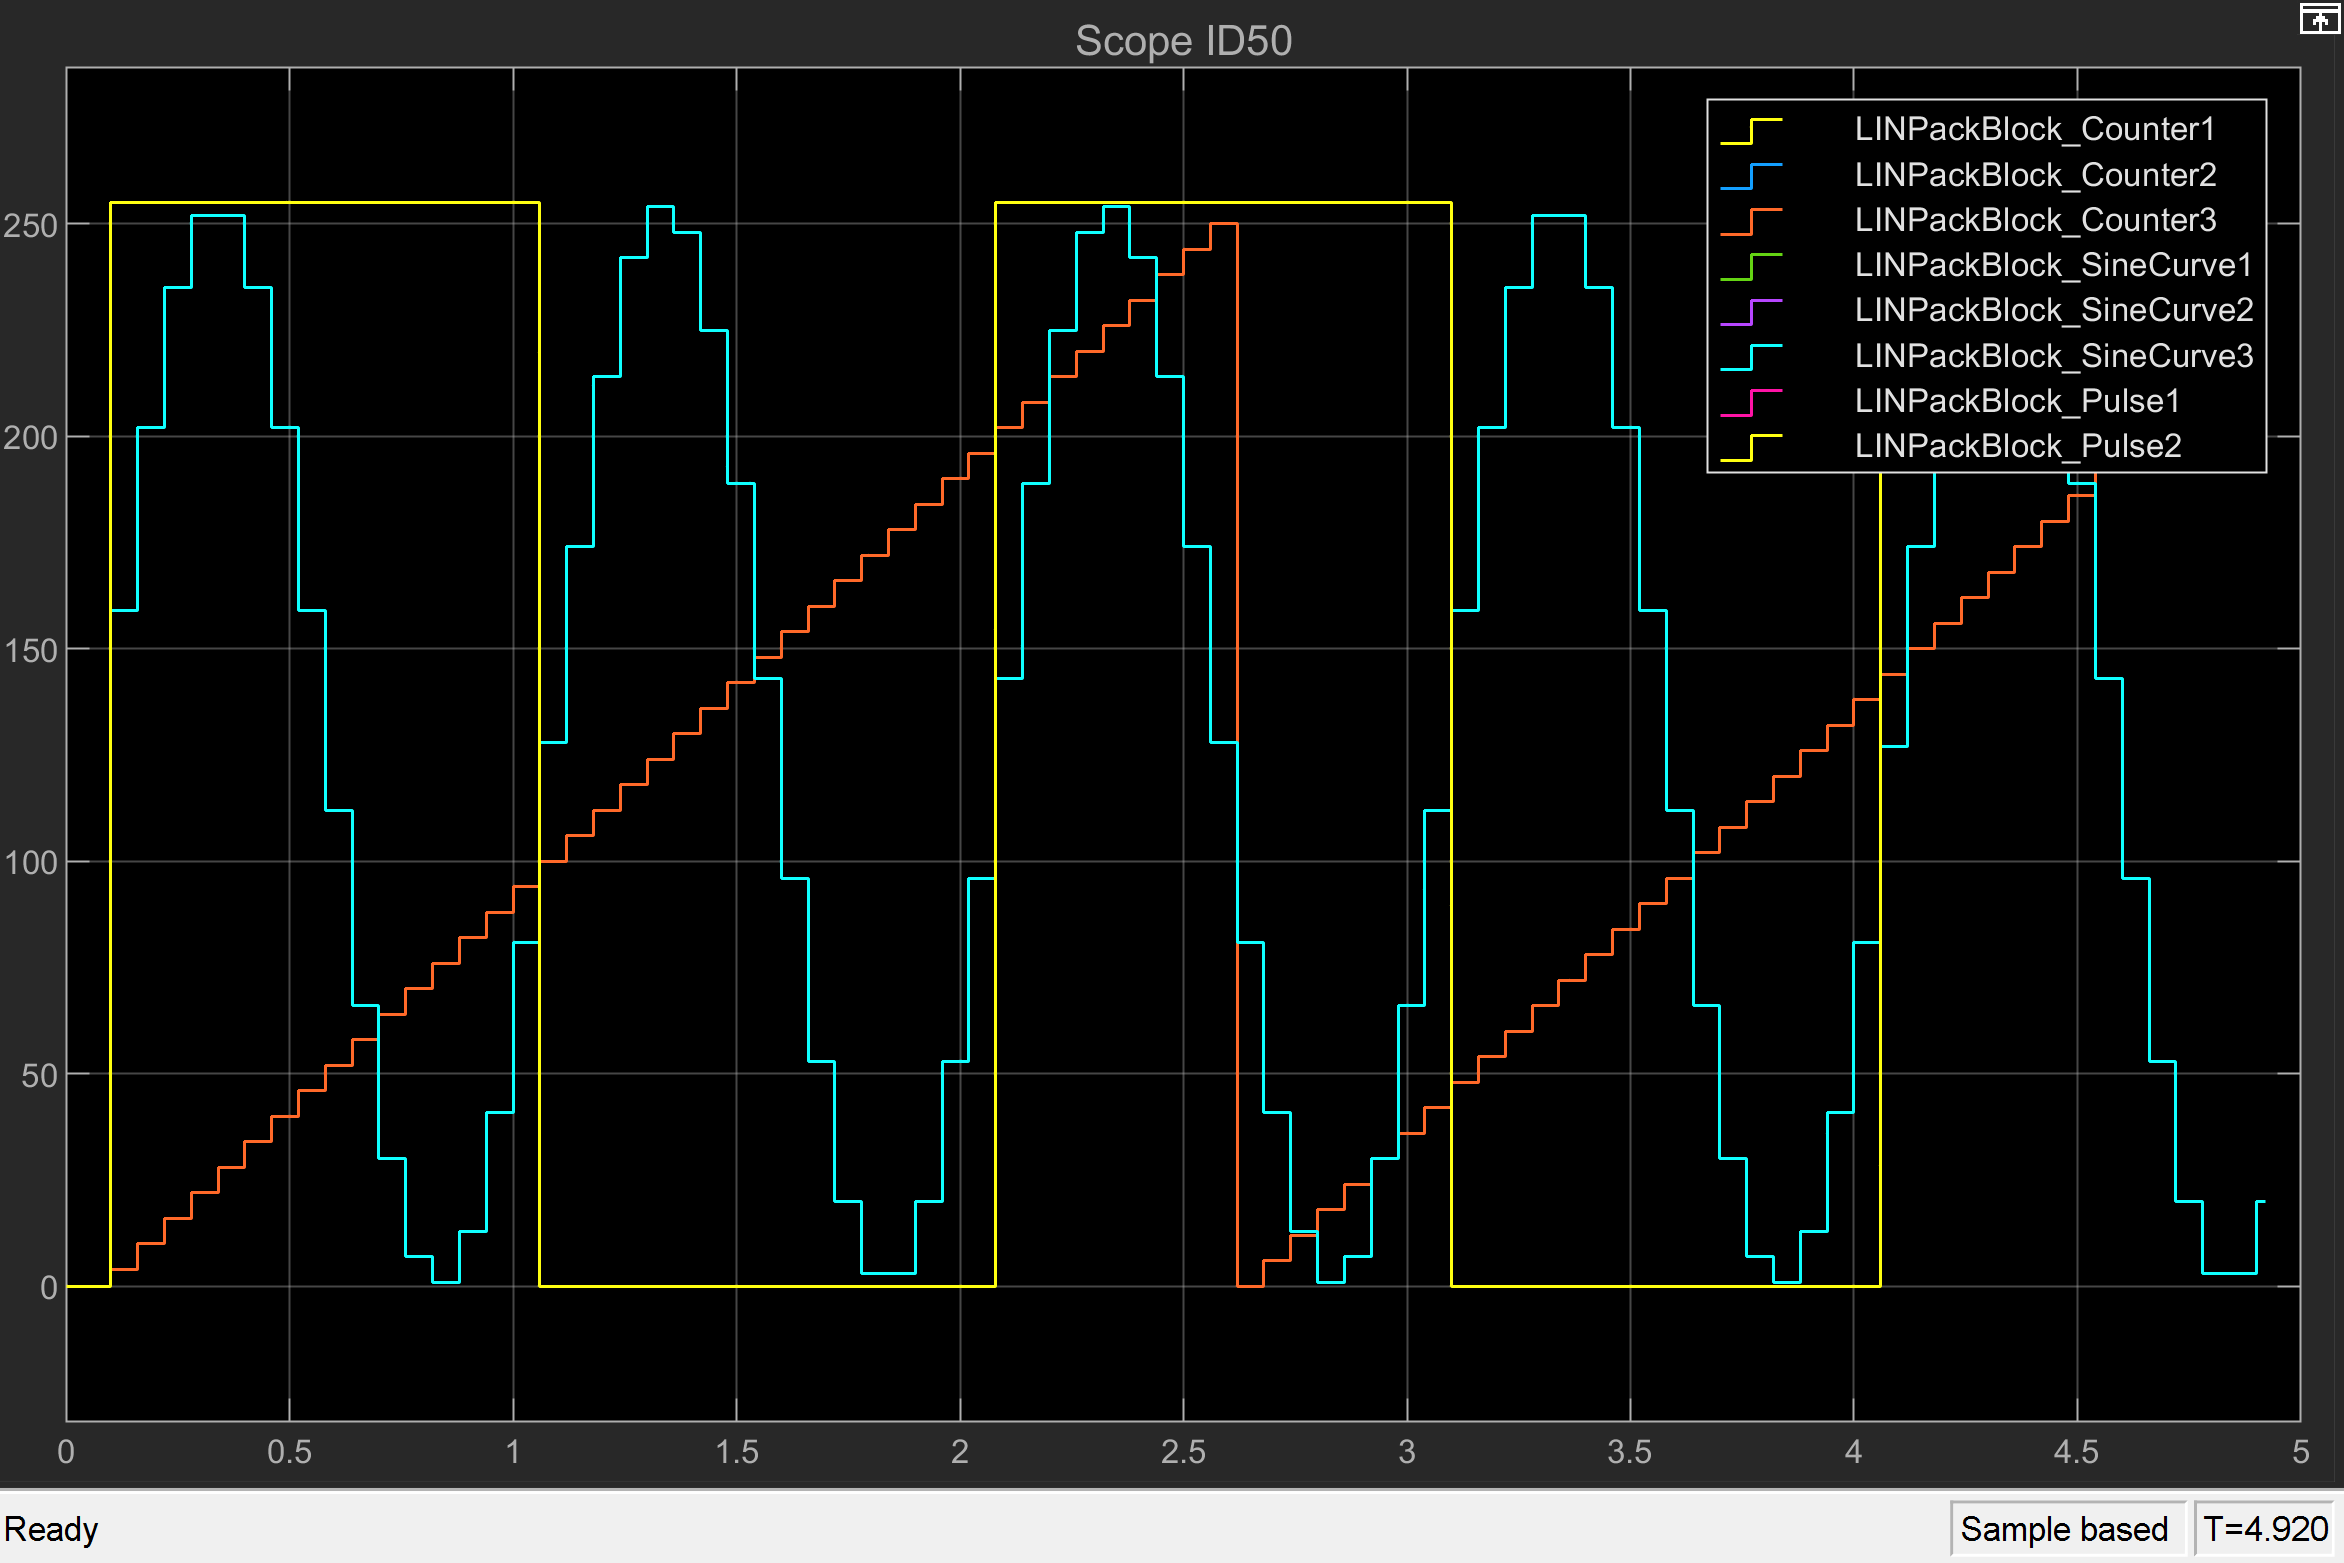

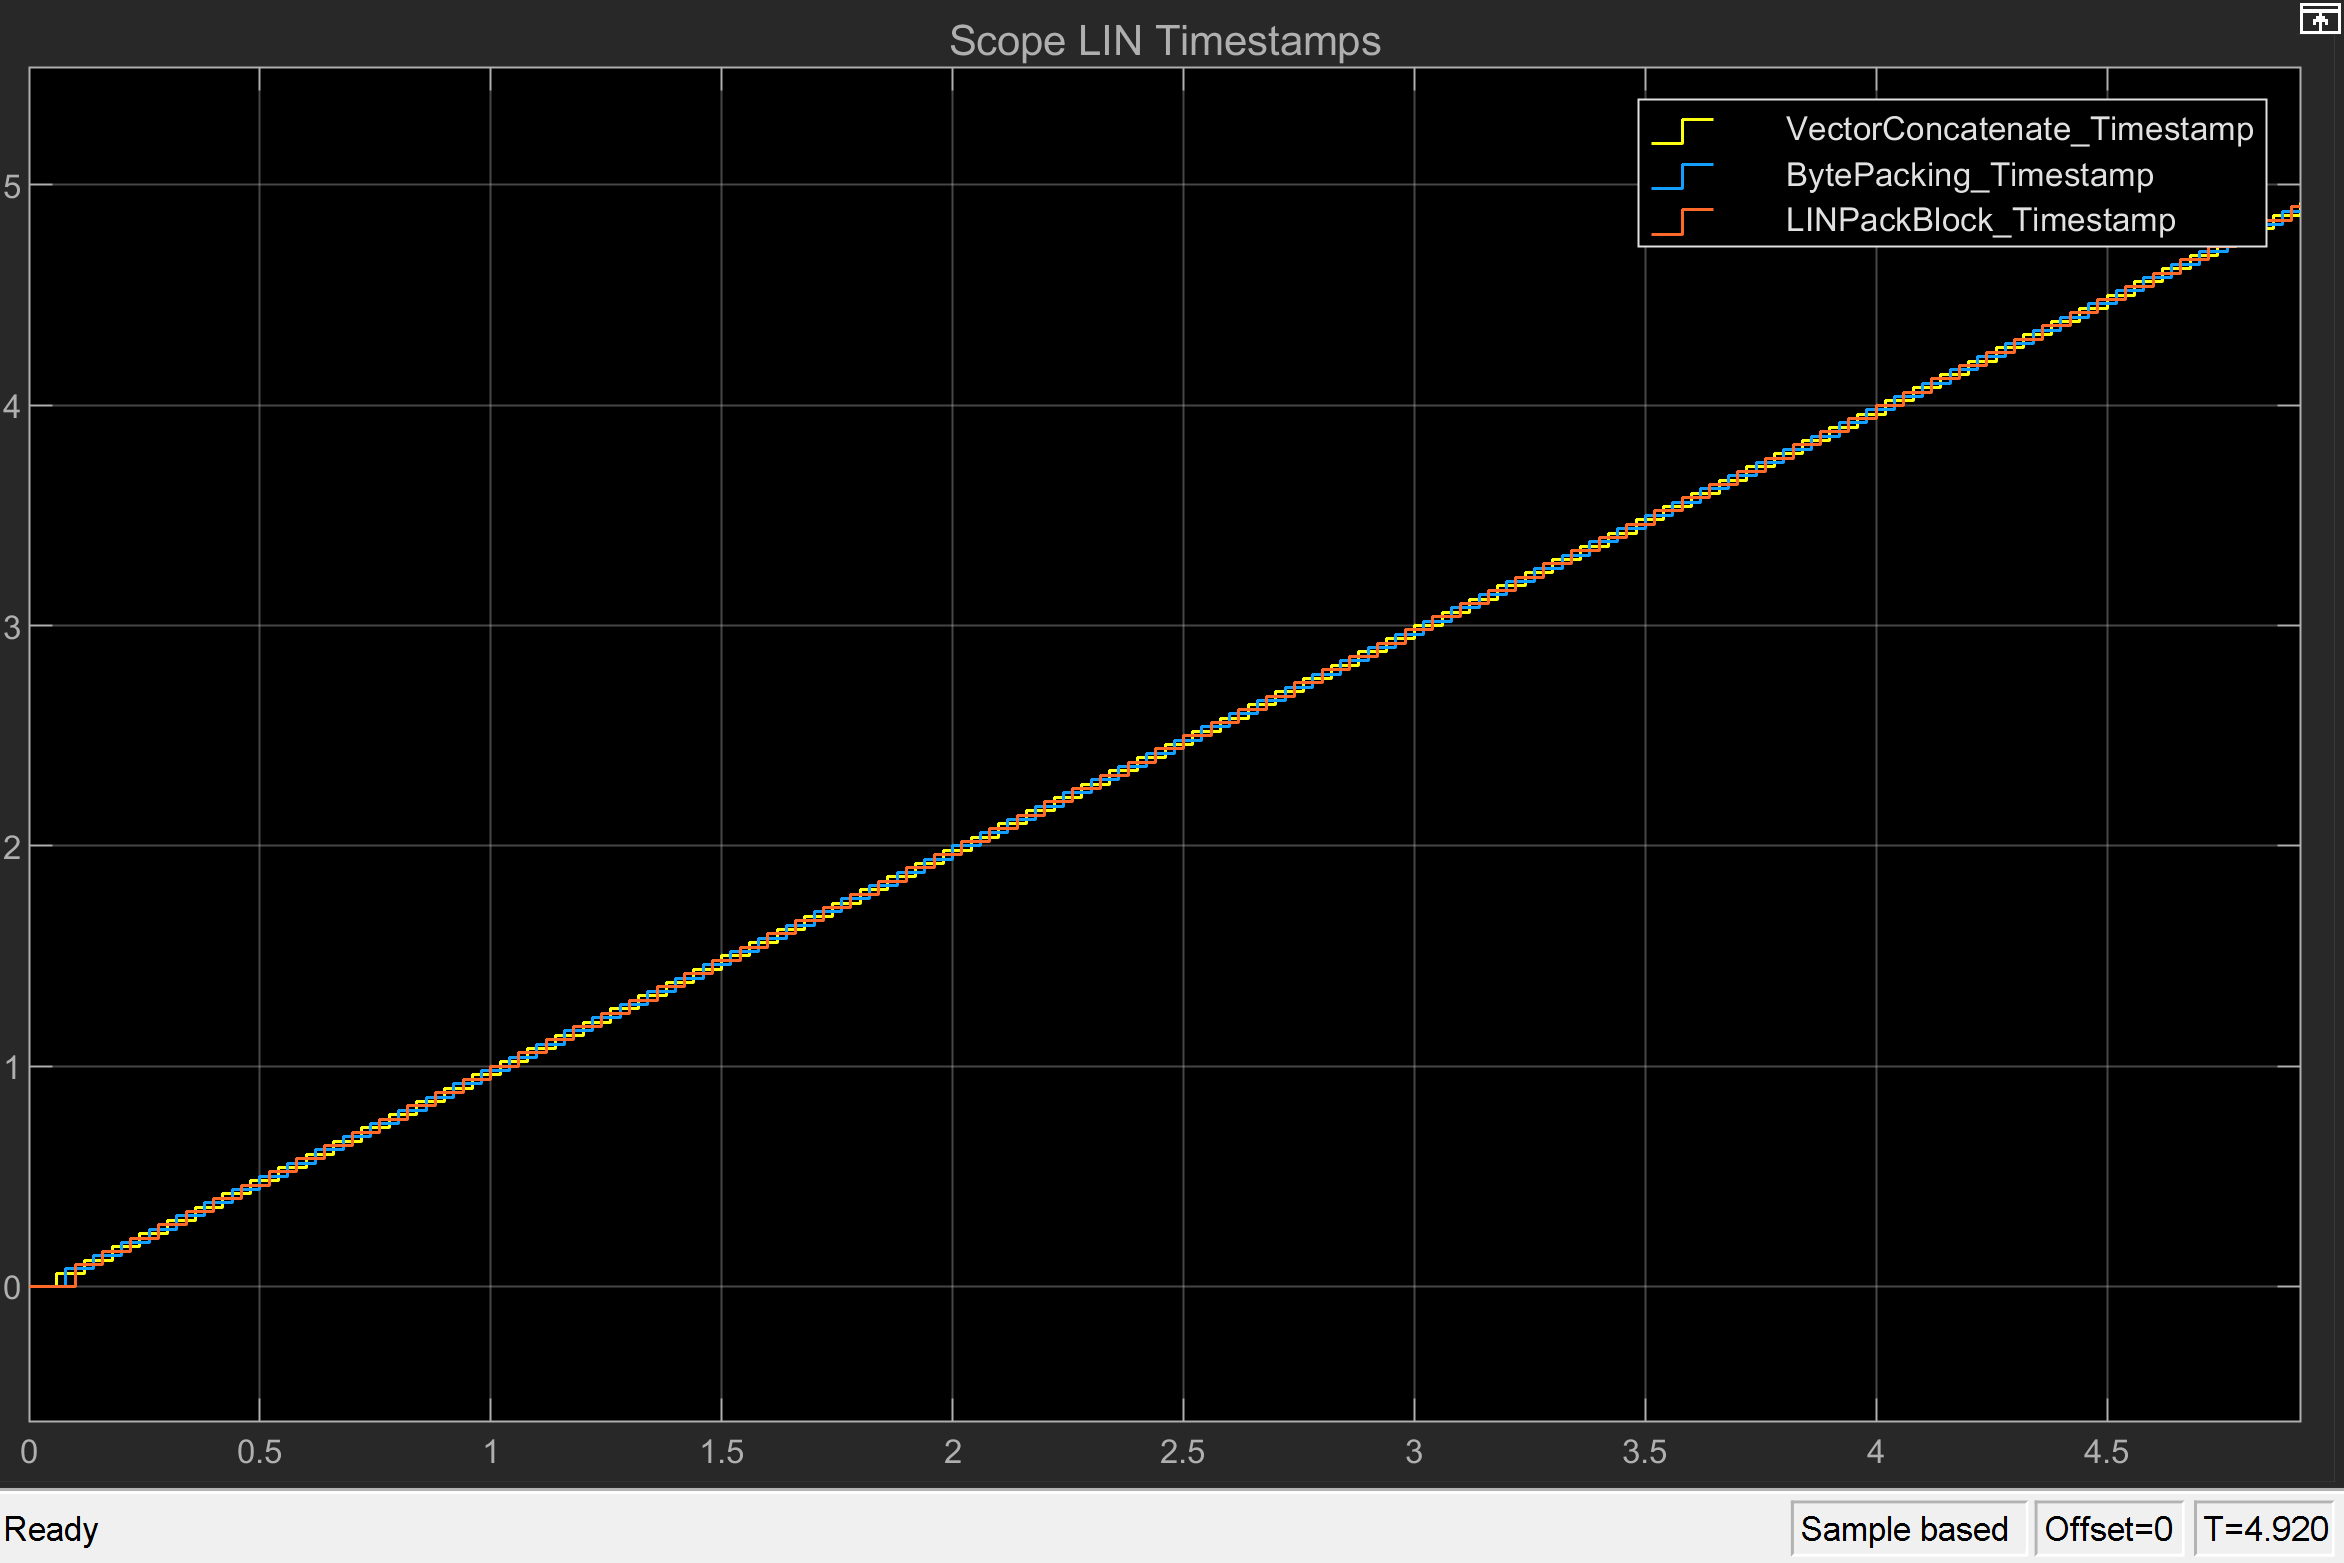

## Additional References

- [IO611 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_2)